folderPath = 'D:\TechnicalReport\nTop Homogenisation';
files = dir(fullfile(folderPath, '*.csv'));
fileNames = {files.name};

% Extract numeric values from fileNames
numericValues = zeros(length(fileNames), 1);
for i = 1:length(fileNames)
    [~, name, ~] = fileparts(fileNames{i});  % Remove .csv extension
    numericValues(i) = str2double(name);
end

% sort based on number
[~, sortedIndices] = sort(numericValues);
sortedFilenames = fileNames(sortedIndices);

% data from CSV files in sorted order
tables = cell(length(sortedFilenames), 1);
for i = 1:length(sortedFilenames)
    filePath = fullfile(folderPath, sortedFilenames{i});
    tables{i} = readtable(filePath);
    tables{i,2} = numericValues(sortedIndices(i));
end

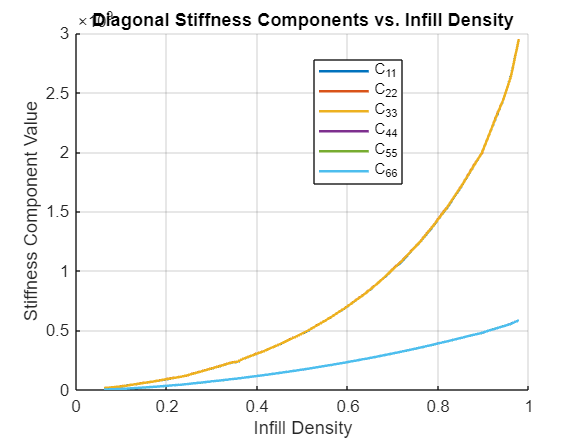

% Extract infill densities and stiffness matrices
numFiles = length(tables);
densities = zeros(numFiles, 1);
stiffnessData = zeros(numFiles, 6, 6); % 3D array: [density, row, col]

for i = 1:numFiles
    densities(i) = tables{i,2};        % Get density from second column
    currentTable = tables{i,1};       % Get 6x6 table from first column
    stiffnessData(i, :, :) = currentTable{:,:}; % Convert table to numeric array
end

figure;
hold on;
for diagIdx = 1:6
    plot(densities, squeeze(stiffnessData(:, diagIdx, diagIdx)), ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('C_{%d%d}', diagIdx, diagIdx));
end
hold off;

xlabel('Infill Density');
ylabel('Stiffness Component Value');
title('Diagonal Stiffness Components vs. Infill Density');
legend('Location', 'best');
grid on;

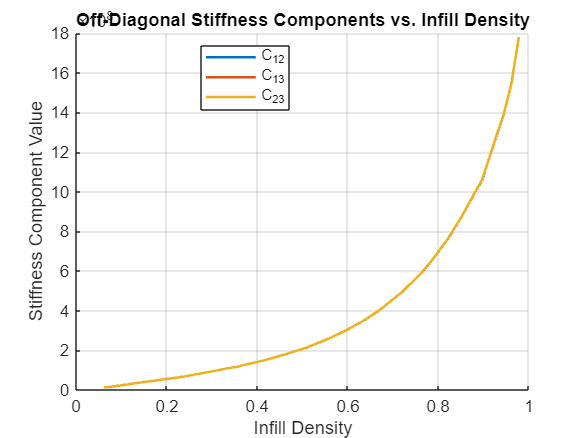


figure;
hold on;
plot(densities, squeeze(stiffnessData(:, 1, 2)), 'LineWidth', 1.5, 'DisplayName', 'C_{12}');
plot(densities, squeeze(stiffnessData(:, 1, 3)), 'LineWidth', 1.5, 'DisplayName', 'C_{13}');
plot(densities, squeeze(stiffnessData(:, 2, 3)), 'LineWidth', 1.5, 'DisplayName', 'C_{23}');
hold off;

xlabel('Infill Density');
ylabel('Stiffness Component Value');
title('Off-Diagonal Stiffness Components vs. Infill Density');
legend('Location', 'best');
grid on;

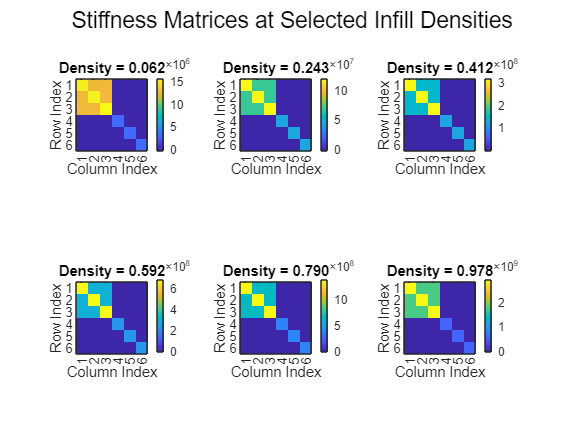

%% Figure 3: Heatmaps of the Full 6x6 Stiffness Matrix at Selected Infill Densities
% Select up to 4 representative densities (e.g. minimum, low, high, maximum)
numSteps = 6;
selected_indices = round(linspace(1, numFiles, min(numFiles,numSteps)));

nCols = ceil(sqrt(numSteps));
nRows = ceil(numSteps / nCols);  
figure;
for j = 1:length(selected_indices)
    idx = selected_indices(j);
    subplot(nRows,nCols,j);
    % Use imagesc to display the stiffness matrix as a heatmap
    imagesc(squeeze(stiffnessData(idx, :, :)));
    colorbar;
    axis square;
    xlabel('Column Index');
    ylabel('Row Index');
    title(sprintf('Density = %.3f', densities(idx)));
    set(gca, 'XTick', 1:6, 'YTick', 1:6);
end
sgtitle('Stiffness Matrices at Selected Infill Densities');

figure;
hold on;

% preallocate
fitResults = cell(6,1); % stores (a, b, R^2)

for diagIdx = 1:6
    x = densities(:);
    y = squeeze(stiffnessData(:, diagIdx, diagIdx));
    y = y(:);
    
    % original data
    plot(x, y, ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('C_{%d%d}', diagIdx, diagIdx));
    
    % exponential regression
    [fitResult, gof] = fit(x, y, 'exp1');
    
    fitResults{diagIdx} = struct(...
        'a', fitResult.a, ...
        'b', fitResult.b, ...
        'Rsquare', gof.rsquare);
    
    % Plot fit
    plot(x, fitResult(x), '--', 'LineWidth', 1.5, ...
        'DisplayName', sprintf('C_{%d%d} Fit', diagIdx, diagIdx));
end

hold off;

% Format and display results
fprintf('\n%-8s %-15s %-15s %-10s\n', 'Component', 'a (coefficient)', 'b (exponent)', 'R²');

Component a (coefficient) b (exponent)    R²        


fprintf('===========================================================\n');

for diagIdx = 1:6
    if isstruct(fitResults{diagIdx})
        res = fitResults{diagIdx};
        fprintf('C_{%d%d}    %-15.4e %-15.4f %-10.4f\n', ...
            diagIdx, diagIdx, res.a, res.b, res.Rsquare);
    else
        fprintf('C_{%d%d}    %s\n', diagIdx, diagIdx, fitResults{diagIdx});
    end
end

C_{11}    6.6422e+07      3.8369          0.9968    
C_{22}    6.6786e+07      3.8317          0.9969    
C_{33}    6.6615e+07      3.8341          0.9969    
C_{44}    3.8522e+07      2.8404          0.9797    
C_{55}    3.8504e+07      2.8409          0.9797    
C_{66}    3.8527e+07      2.8402          0.9797    


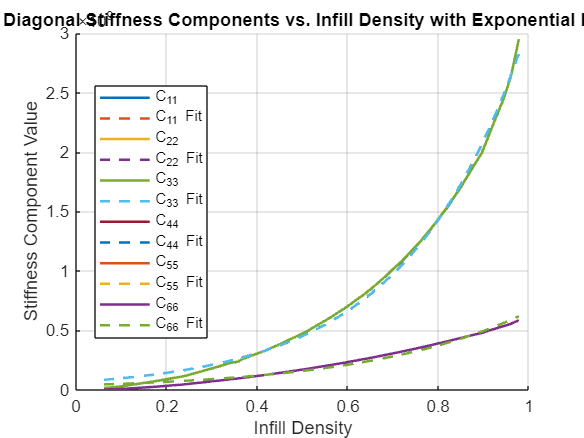


xlabel('Infill Density');
ylabel('Stiffness Component Value');
title('Diagonal Stiffness Components vs. Infill Density with Exponential Fit');
legend('Location', 'best');
grid on;


% equation y=a⋅e^b⋅x